# ASE387P Homework 3

## Problem 1

clear; clc

### Part a-b

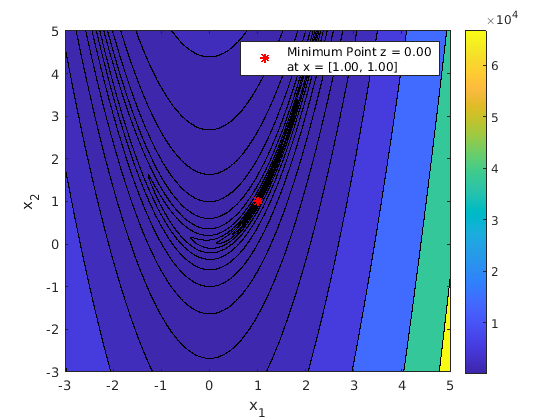

f = @(x) (1-x(1))^2 + 100*(x(2)-x(1)^2)^2;
del = 0.01;
x1 = -3:del:5;
x2 = -3:del:5;
z = zeros(length(x1));
for i = 1:length(x1)
    for j = 1:length(x1)
        z(j, i) = f([x1(i), x2(j)]); 
    end
end
contourf(x1, x2, z, [logspace(-4, 5, 22), max(max(z))*0.85], 'HandleVisibility',"off")
colorbar
[val, idx1] = min(z);
[val, idx2] = min(val);
idx1 = idx1(idx2);
hold on
scatter(x1(idx2), x2(idx1), 'r*', 'DisplayName', ...
    sprintf('Minimum Point z = %0.2f \nat x = [%0.2f, %0.2f]', val, x1(idx2), x2(idx1)), ...
    'linewidth', 1.5)
legend
hold off
xlabel('x_1'); ylabel('x_2')

% exportgraphics(gcf, 'hw3p1a.png', 'Resolution', 200)

### Part c

syms x_1 x_2
f_sym = (1-x_1)^2 + 100*(x_2-x_1^2)^2

$$f\_sym = {\left(x_{1}-1\right)}^{2}+100\,{\left(x_{2}-{x_{1}}^{2}\right)}^{2}$$

eqs = [diff(f_sym, x_1) == 0; diff(f_sym, x_2) == 0]

$$eqs = \left(\begin{array}{c} 2\,x_{1}-400\,x_{1}\,\left(x_{2}-{x_{1}}^{2}\right)-2=0\\ 200\,x_{2}-200\,{x_{1}}^{2}=0 \end{array}\right)$$

sol = solve(eqs); fprintf('Derivatives = 0 \nat x = [%0.2f, %0.2f]', sol.x_1, sol.x_2)

Derivatives = 0 
at x = [1.00, 1.00]

#### 2nd Order Necessary and Sufficient Condition

Necessary: $\nabla f(x_\ast) = \vec{0}$

Sufficient: $\nabla^2f(x_\ast)$ is positive definite

grad = [diff(f_sym, x_1); diff(f_sym, x_2)]

$$grad = \left(\begin{array}{c} 2\,x_{1}-400\,x_{1}\,\left(x_{2}-{x_{1}}^{2}\right)-2\\ 200\,x_{2}-200\,{x_{1}}^{2} \end{array}\right)$$

f_grad_ = matlabFunction(grad);
fprintf('Norm of the first gradient of f is %0.2f,\n thus the necessary condition is satisfied', norm(f_grad_(sol.x_1, sol.x_2)))

Norm of the first gradient of f is 0.00,
 thus the necessary condition is satisfied

grad = [diff(grad(1), x_1) diff(grad(1), x_2);
    diff(grad(2), x_1) diff(grad(2), x_2)]

$$grad = \left(\begin{array}{cc} 1200\,{x_{1}}^{2}-400\,x_{2}+2 & -400\,x_{1}\\ -400\,x_{1} & 200 \end{array}\right)$$

f_grad2_ = matlabFunction(grad);
[A, flag] = chol(f_grad2_(sol.x_1, sol.x_2))

$$A = \left(\begin{array}{cc} \sqrt{802} & -\frac{200\,\sqrt{802}}{401}\\ 0 & \frac{10\,\sqrt{2}\,\sqrt{401}}{401} \end{array}\right)$$

flag = 0

fprintf('As the Cholesky factorization was successful, and returned a flag of %i\n the sufficient condition was satisfied', flag)

As the Cholesky factorization was successful, and returned a flag of 0
 the sufficient condition was satisfied

## Problem 2

% SETUP
s = [-1 1].';
x0 = [4 -1].';
t0 = 0.1;
f_grad = @(x) f_grad_(x(1), x(2));
f_grad2 = @(x) f_grad2_(x(1), x(2));

% BRACKETING MINIMUM
f_search = f(x0);
x_search = x0;
t = t0;
iter = 1;
while length(f_search) < 2 || f_search(end) < f_search(end-1)
    % INCREASING STEP SIZE IF NOT BRACKETING
    if iter == 4
        t = 2*t;
        iter = 0;
    end
    x_search = cat(2, x_search, x_search(:, end) + t*s);
    f_search(end+1) = f(x_search(:, end));
    iter = iter+1;
end


% QUADRATIC POLYNOMIAL LINE SEARCH
% tol = abs(max(f_search) - min(f_search))/max(1e-8, min(f_search))
alpha = -(f_grad(x_search(:, end-1)).'*s) / (s.' * f_grad2(x_search(:, end-1)) * s);
xstara = x_search(:, end-1) + alpha*s

xstara =     1.3025
    1.6975


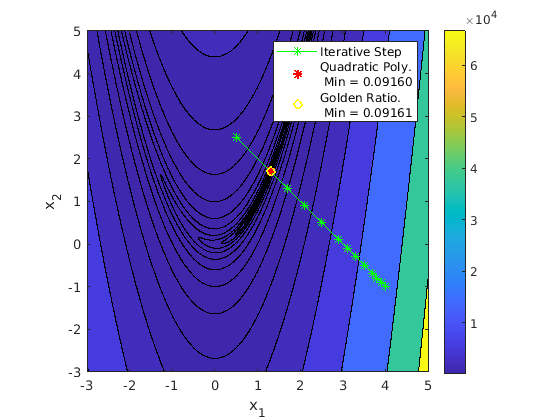


% GOLDEN RATIO LINE SEARCH
alpha = (3 - sqrt(5))/2;
xL = x_search(:, end-2);
xR = x_search(:, end);
xtmp1 = xL + alpha*(xR - xL);
xtmp2 = xR - alpha*(xR - xL);
ftmp1 = f(xtmp1);
ftmp2 = f(xtmp2);

for i = 1:15
    if ftmp1 > ftmp2
        xL = xtmp1;
        xtmp1 = xtmp2; 
        xtmp2 = xR - alpha*(xR - xL);
    else
        xR = xtmp2;
        xtmp2 = xtmp1; 
        xtmp1 = xL + alpha*(xR - xL);
    end
    ftmp1 = f(xtmp1);
    ftmp2 = f(xtmp2);
    
%     [f(xtmp1), f(xtmp2)]
    xstarb = [xtmp1 xtmp2];
    [val, idx] = min([f(xtmp1), f(xtmp2)]);
    xstarb = xstarb(:, idx);
end

% PLOTTING
contourf(x1, x2, z, [logspace(-4, 5, 22), max(max(z))*0.85], 'HandleVisibility',"off")
colorbar
[val, idx1] = min(z);
[val, idx2] = min(val);
idx1 = idx1(idx2);
hold on
% scatter(x1(idx2), x2(idx1), 'r*', 'DisplayName', ...
%     sprintf('Minimum Point z = %0.2f \nat x = [%0.2f, %0.2f]', val, x1(idx2), x2(idx1)), ...
%     'linewidth', 1.5)
plot(x_search(1, :), x_search(2, :), 'g*-', 'DisplayName', 'Iterative Step')
scatter(xstara(1), xstara(2), 'r*', 'DisplayName', ...
    sprintf('Quadratic Poly.\n Min = %0.5f', f(xstara)), ...
    'linewidth', 1.5)
scatter(xstarb(1), xstarb(2), 'yo', 'DisplayName', ...
    sprintf('Golden Ratio.\n Min = %0.5f', f(xstarb)), ...
    'linewidth', 1.5)
legend
axis equal
hold off
xlabel('x_1'); ylabel('x_2')
exportgraphics(gcf, 'hw3p2.png', 'Resolution', 200)